# 7. Loops

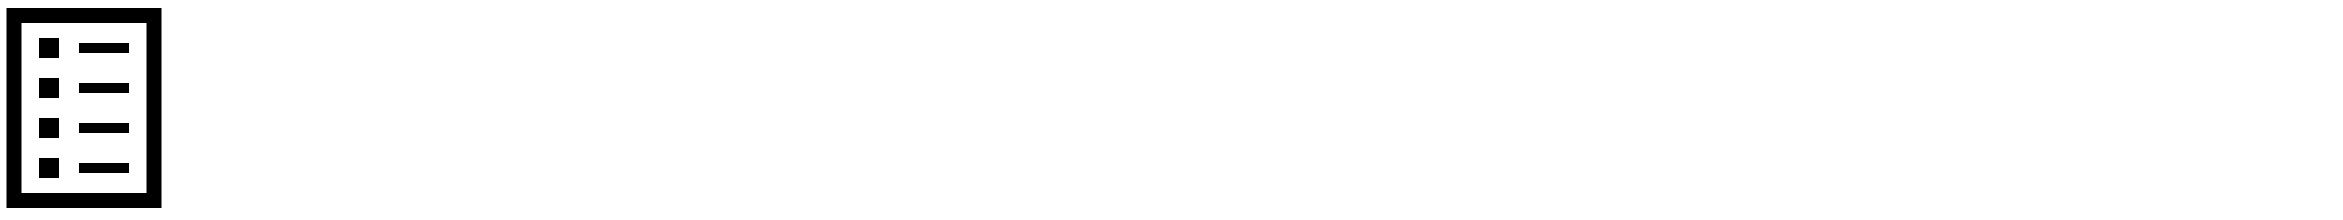

There are two basic types of loops including `for` and `while`. An example of a loop is to check the temperature of the egg every second and adjust the heater. The loop may continue for a determine amount of time or until a certain condition is met.

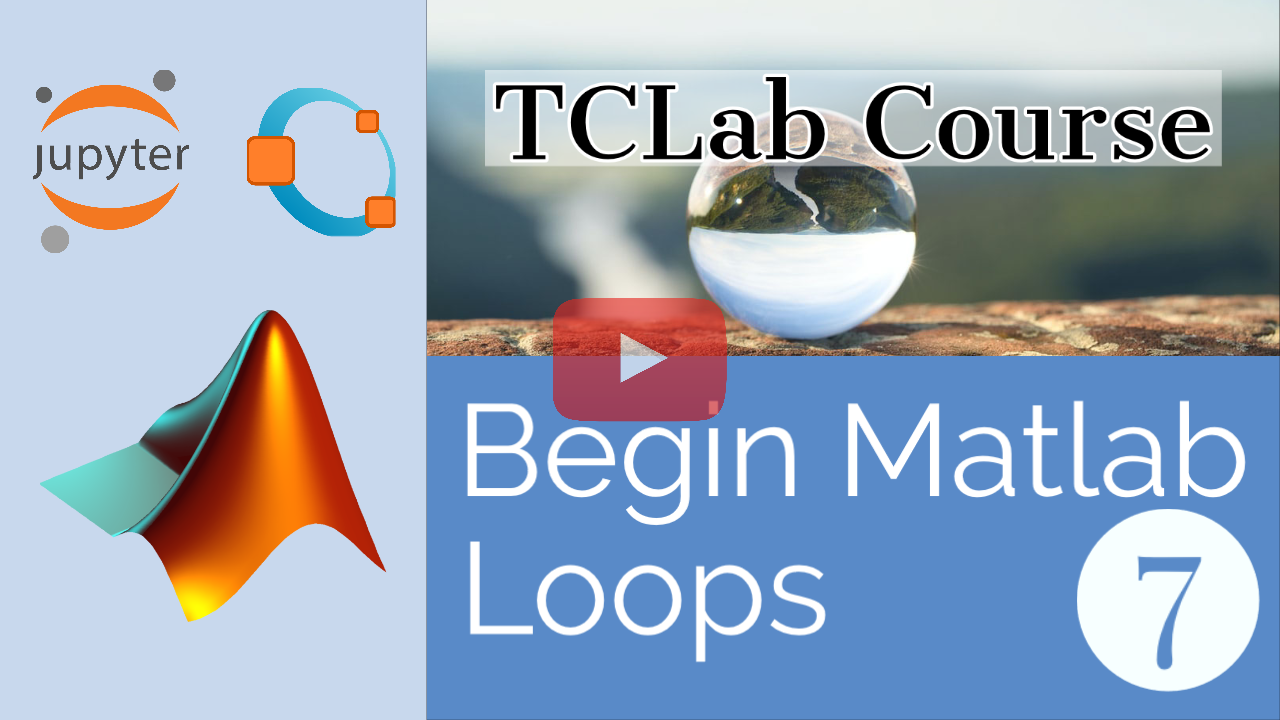

[Click here to watch the video: Matlab 👩‍💻 For and While Loops](https://www.youtube.com/watch?v=1L_72OkRD7k&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

### **While Loops**

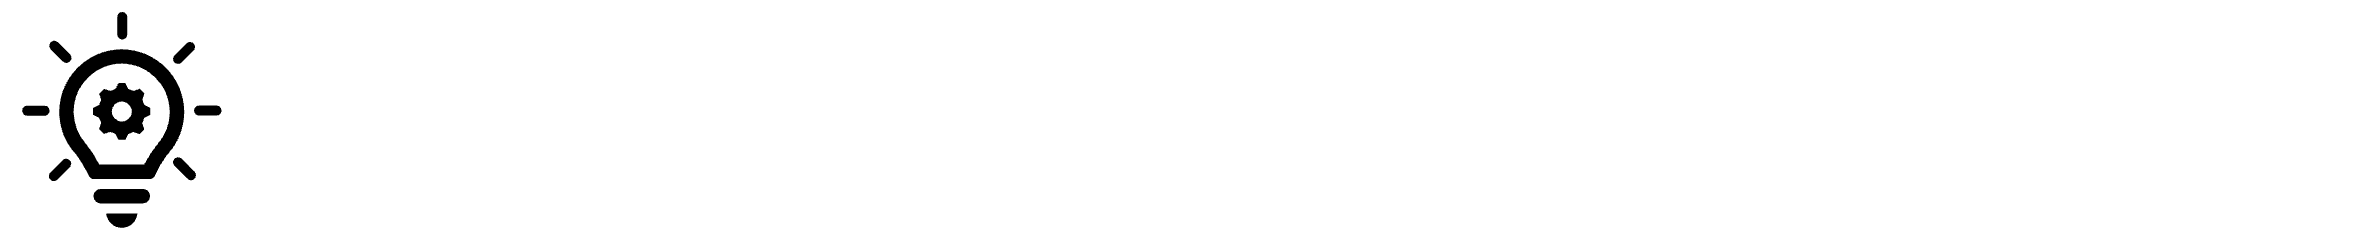

While loops work by repeating until the condition becomes `false`. The way they are coded can almost be said as a sentence. `while x > 0:` While x is greater than 0.

A `while` loop can get stuck in an infinite loop if the condition for termination is never met. You can stop the infinite loop by setting the value of `true` to become `false` in many ways. In the code below, the infinite loop is broken by making `x` one less each time it goes through the loop, with `x = x - 1`.

See how the loop changes by changing the value of `x`.

disp('Are you done yet?')

x = 8;                                   % Change this number

while x >= 5                             % Code stops when x is less than or equal to 5    
    disp(["Almost done ", num2str(x)]);  % Uses the value in the loop    
    x = x - 1;                           % Makes x one less each loop
end

Tip: `x = x - 1` can be simplified into `x -= 1`. They mean the same thing, it's just a little shorter. This is true for most other math operators. `+=`, `*=`, `/=`, are all valid operators.

x = 5;
x *= 3;
disp(x)

Another thing used in while loops is the `==` symbols. Just one `=` means you are assigning a variable, but you shouldn't do that in the condition that tells the `while` loop when to end. Instead use the `==` to tell the code you are comparing the two values. For example:

`    while` `x` `==` `0`

This while loop continues while `x` is equal to zero. This example also shows how to create nested loops.

x = 0;

disp('First While Loop')
while x == 0    
    disp(x)    
    x += 1;    
    disp('Second (Nested) While Loop')    
    while x <= 3        
        disp(x)        
        x += 1;    
    end
end
disp('Third While Loop')
while x <= 5    
    disp(x)    
    x += 1;
end

### **For Loops**

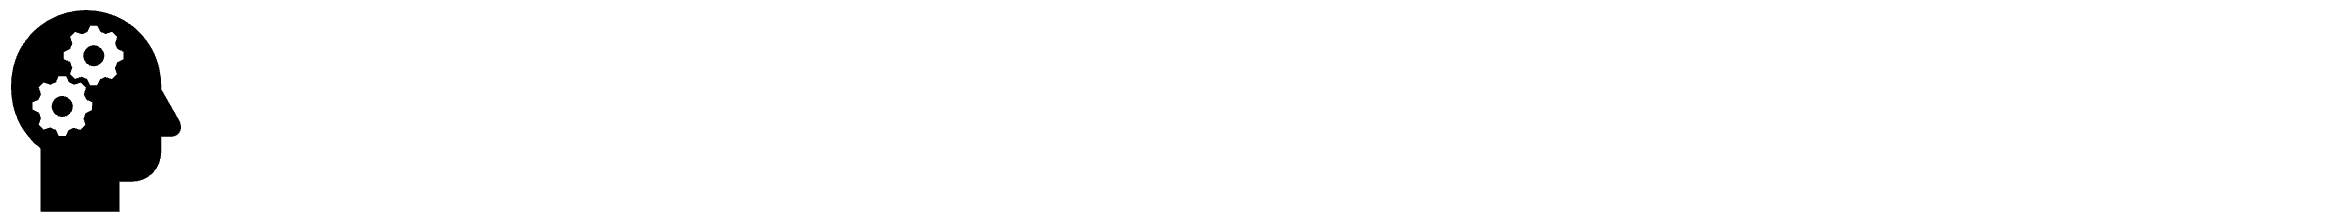

For loops are when you already know the number of times the loop should repeat. A `while` loop is when you don't know the number of times to cycle through the instructions when you start. They are formatted `for i = 1:4`. The `i` is just a typical iterator. You can enter any variable name you like instead of `i`.

The `i`, is used to keep track of the current loop count. The numbers to the right of the `=` indicate what values the `for` loop iterates through.

#### **Variable**

You can also enter a variable to control the number of `for` loop cycles such as the use of `y`. The variable is used in the `for` loop to determine the number of cycles.

disp('Echos in a canyon:')
y = 5
for i = 1:y    
    disp('hello')
end

#### **Using** `i`

In a `for` loop the `i` variable, in `for i=start:stop`, can be used during the repeating loop. Every time the for loop goes again, the value of `i` goes to the next value. You can use `i` in a loop to do different things based on the cycle number. This is similar to the `while` loop example where we used this code: `disp(["Almost done ",num2str(x)])`

disp('Loop 1')
for i =1:5    
    disp(i)
end
disp('Loop 2: Count-up by 2s')
for i = 0:2:9    
    disp(i)
end
disp('Loop 3: Count-down by 2s')
for i = 10:-2:0    
    disp(i)
end

### **Activity**

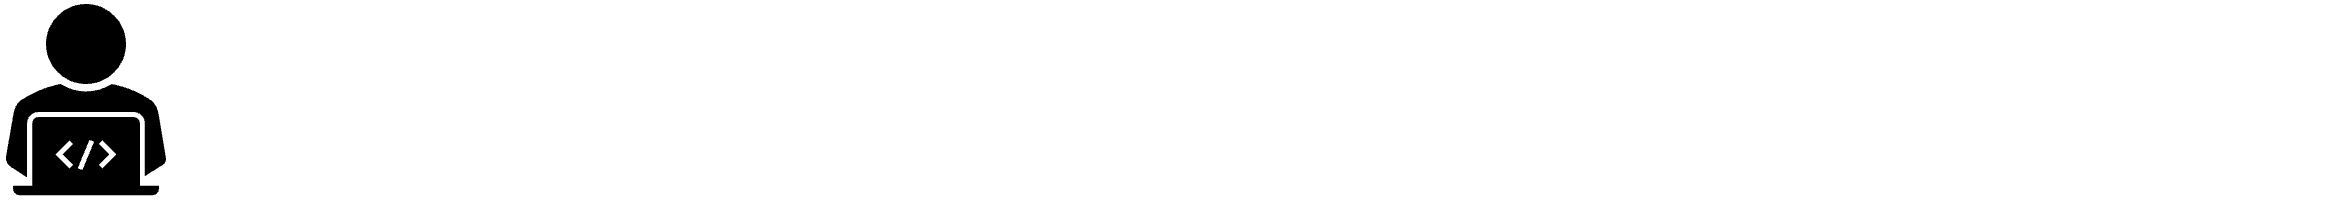

Create a `for` loop that prints out each letter of your name, **backwards**.

`    char_array``(``i``)`

This function finds the index of a string. The first character of `[hi]` is `h` and the second character is `i`.

`    length``(``string``)`

The length function gives the length of a string. `length(waffles)` is `7`.

name = "enter your name";
for i = 1:length(name)    
    disp(name(i))
end

When you run code that turns on the heaters, make sure they work by putting your hand over them or observing the thermochromic paint turn pink when they are over 37°C. Go over Lesson 6 Functions TCLab again, if you don't remember them.

Make a while loop that blinks on and off the **Hot** LED light. If the temperature gets above 28°C, then turn on the light on, and turn off and disconnect the lab after 3 seconds. It is also useful to print the temperature to see if the program works.

lab = tclab;

% Set both heater powers on before the while loop

% Make a while loop

Make a `for` loop that makes the LED percent go all the way from 100 to 0 in steps of 1. Include a 0.1 second pause in between each step with `pause(0.1)`.

lab = tclab;
for i =  % Needs to go from 100 to 0    
    pause(0.1)
end